train_x_len = 20;
test_x_len = 10;
num_class = 10;

Načítanie reťazca, ktorý bude obsahovať názvy všetkých podpriečinkov

topLevelFolder = 'DatasetDynGesta'; % or whatever, such as 'C:\Users\John\Documents\MATLAB\work'
% Get a list of all files and folders in this folder.
files = dir(topLevelFolder);
% Get a logical vector that tells which is a directory.
dirFlags = [files.isdir];
% Extract only those that are directories.
subFolders = files(dirFlags); % A structure with extra info.
% Get only the folder names into a cell array.
subFolderNames = {subFolders(3:end).name}; % Start at 3 to skip . and ..

in_folders = string(subFolderNames); % Návzy podpriečinkov
n_folds = length(in_folders); % Počet podpriečinkov

XTrain = [];
YTrain = [];
XTest = [];
YTest = [];
XData = [];
YData = [];
class_idx = [8 5 4 9 1 7 6 3 2 0];

Načítanie dát

% Prechádzanie všetkých podpriečinkov, a ukladanie trenovacich a testovacich dat
for folds_ixd = 1:n_folds
    XData = [];
    YData = [];
    files_path = strcat(in_folders(folds_ixd),'\'); % Cesta k aktuálnemu priečinku
    files = dir(fullfile(topLevelFolder,files_path,'*.txt')); % Získanie názvov všetkých súborov v aktuálnom priečinku
    for file_idx = 1:length(files)
            file_name = fullfile(topLevelFolder,files_path, files(file_idx).name);
            data = dlmread(file_name, ';');% čítanie aktuálneho súboru
            %správne otočenie dát
            data_x = data(:,1)-min(data(:,1));
            data_y = abs(data(:,2)-max(data(:,2)));
            data(:,1) = data_x;
            data(:,2) = data_y;
            cel_data(file_idx,1) =num2cell(data', [1 2]); 
    end

    %nacitanie vozriek
    XData = [XData; cel_data(randi([1 length(files)], [train_x_len+test_x_len+20 1]))];
    YData = [YData, linspace(class_idx(folds_ixd), class_idx(folds_ixd), train_x_len+test_x_len+20)];

    XDataFiltered = [];
    YDataFiltered = [];
    for(i=1:train_x_len+test_x_len+10)  %orezanie malych a velkych vzoriek
        dataLenght = size(XData{i,1},2);
        if (dataLenght < 40 || dataLenght > 200)
            continue;
        end
        XDataFiltered = [XDataFiltered;XData(i)];
        YDataFiltered = [YDataFiltered,YData(i)];
    end

    XData = XDataFiltered;
    YData = YDataFiltered;

    %rozdelenie vzoriek medzi trenovacie a testovacie data
    for i=1:train_x_len
        XTrain = [XTrain;XData(i,:)];
        YTrain = [YTrain,YData(i)];
    end
    for i=1:test_x_len
        XTest = [XTest;XData(i+train_x_len,:)];
        YTest = [YTest,YData(i+train_x_len)];
    end
end




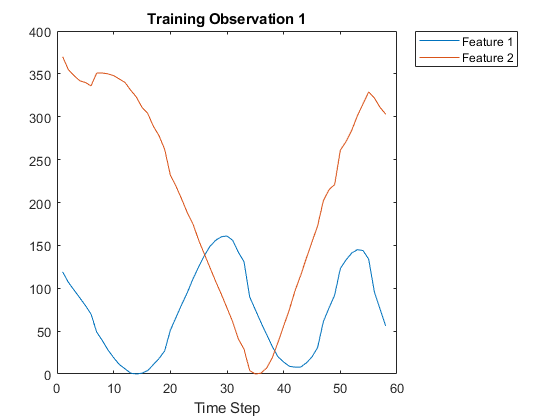

YTrain = categorical(YTrain');
YTest = categorical(YTest');

figure
plot(XTrain{1}')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

Vykreslenie vzorky

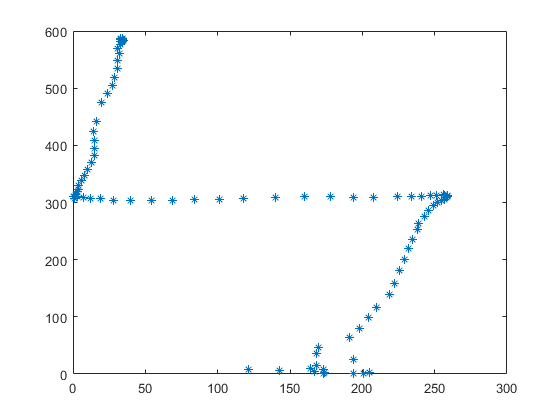

x=XTrain{50,1};
figure;clf;
% plot(x(1,:)-min(x(1,:)),abs(x(2,:)-max(x(2,:))),'*');
plot(x(1,:),x(2,:),'*');

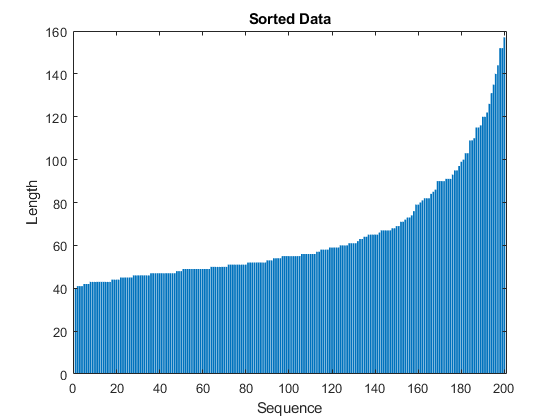


numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end


[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

figure
bar(sequenceLengths)
% ylim([0 30])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

Struktura LSTM siete

inputSize = 2;
numHiddenUnits = 100;
numClasses = 10;
maxEpochs = 20;
miniBatchSize = 20;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         10 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

Trénovanie siete

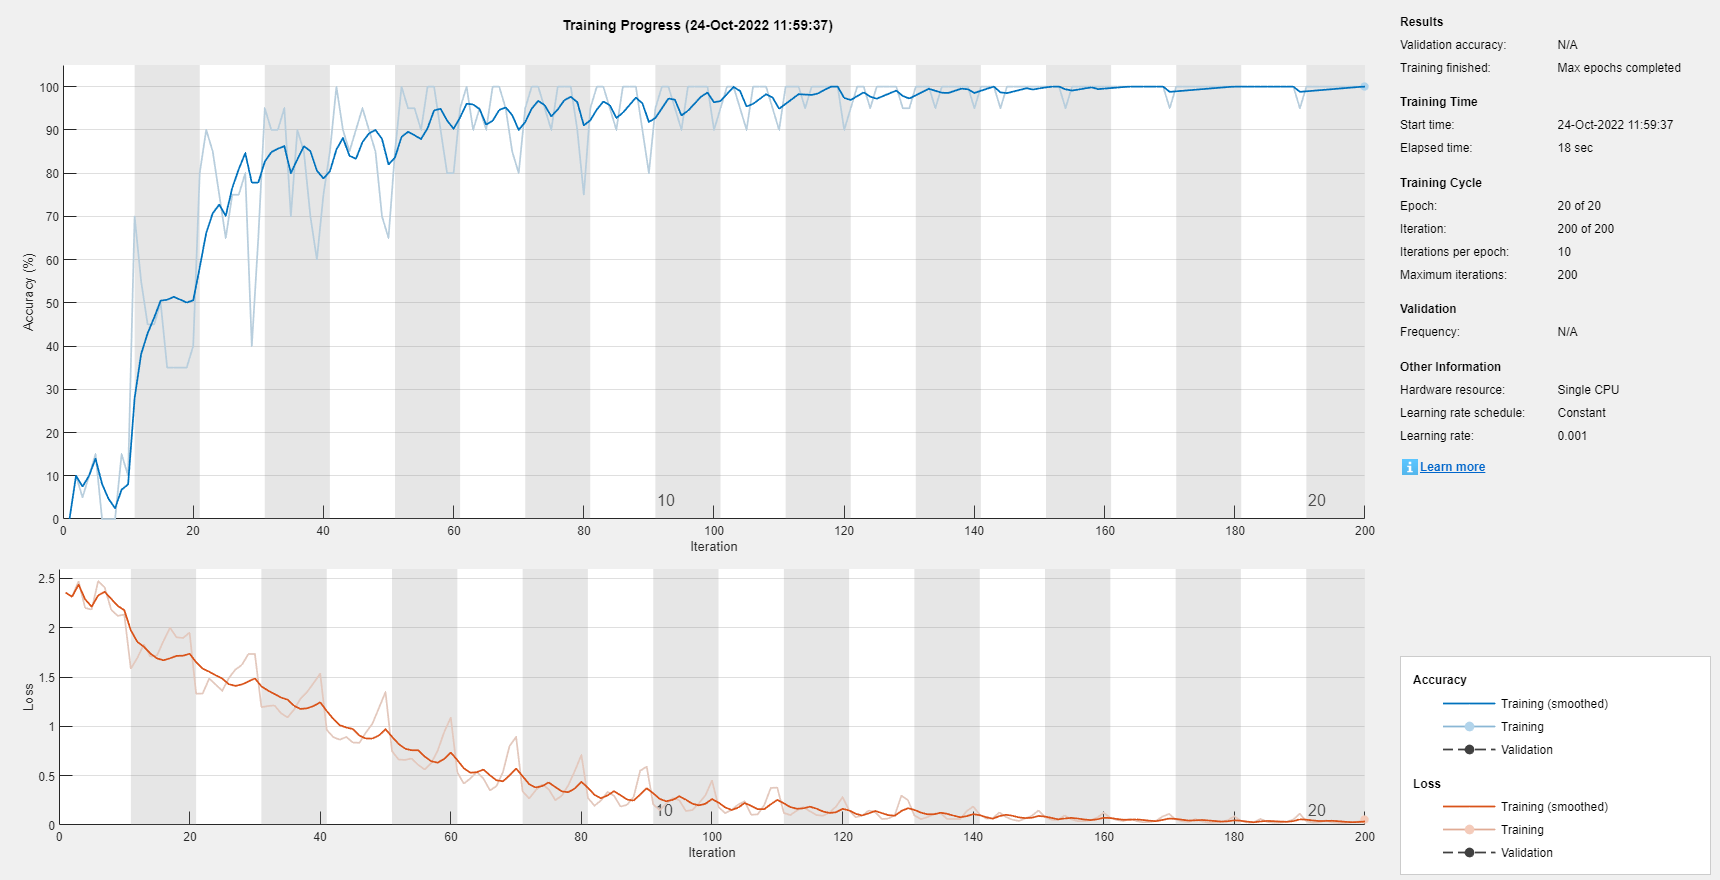


options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);

Vyhodnotenie uspesnosti - testovacie data


% [XTest,YTest] = japaneseVowelsTestData;
% XTest(1:3)
numObservationsTest = numel(XTest);
sequenceLengthsTest = zeros(1,numObservationsTest);


for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end
[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

miniBatchSize = 27;
YPred = classify(net,XTest, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');
test_acc = sum(YPred == YTest)./numel(YTest)

test_acc = 0.9100

Vyhodnotenie uspesnosti - trenovacie data

numObservationsTest = numel(XTrain);
sequenceLengthsTest = zeros(1,numObservationsTest);
for i=1:numObservationsTest
    sequence = XTrain{i};
    sequenceLengthsTest(i) = size(sequence,2);
end
[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

miniBatchSize = 27;
YPred = classify(net,XTrain, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');
train_acc = sum(YPred == YTrain)./numel(YTrain)

train_acc = 0.9900

save('runs\zad_2_LSTM_200samp.mat')